%% #2 Microbial inactivation 
%enter all parameter values given in the HW
c=70; B=.0141; cmB=c-B;
Tr= 57.98   ;Dr=  3.3  ;z=  4.68  ; logN0 = 9.6;
t=0:60; %times, min
%define function to compute temperature values for all times t
T=@(t,c,cmB) (49.5+10.5*(  ( (t+c) - sqrt( (t+c).^2 -4*cmB*t  )  )  /  (2*cmB)    ))  ;
%compute temp
Temp=T(t,c,cmB)

Temp =   49.500000000000000  49.649999562114374  49.799998222710443  49.949995941439454  50.099992675508922  50.249988379494837  50.399983005136221  50.549976501110280  50.699968812785634  50.849959881951499  50.999949646519681  51.149938040196396  51.299924992120118  51.449910426461443  51.599894261980076  51.749876411533613  51.899856781531824  52.049835271329279  52.199811772548003  52.349786168320612  52.499758332442809  52.649728128422353  52.799695408409342  52.949660011990339  53.099621764825564  53.249580477104821  53.399535941793474  53.549487932634385  53.699436201865197  53.849380477602693  53.999320460836074  54.149255821959279  54.299186196757816  54.449111181747369  54.599030328738699  54.748943138474935  54.898849053151295  55.048747447581491  55.198637618716639  55.348518773147056  55.498390012119586  55.648250313475117  55.798098509742658  55.947933261401928  56.097753024025828  56.247556007606278  56.397340125808391  56.547102932123735  56.696841538808215  56.84655251


%sent up the integrand
intgrnd =        10.^( (Temp-Tr)/z )          

intgrnd =    0.015418218217089   0.016599131922260   0.017870486361055   0.019239206983016   0.020712749420262   0.022299140057913   0.024007019706354   0.025845690612063   0.027825167061733   0.029956229853761   0.032250484931965   0.034720426498794   0.037379504949282   0.040242199992858   0.043324099357876   0.046641983503504   0.050213916795664   0.054059345638041   0.058199204086054   0.062656027511250   0.067454074925959   0.072619460623484   0.078180295837753   0.084166841178376   0.090611670652691   0.097549848145752   0.105019117292514   0.113060105743847   0.121716544899568   0.131035506257483   0.141067655607497   0.151867526384064   0.163493813578386   0.176009689703407   0.189483144399125   0.203987349361984   0.219601050378617   0.236408988338672   0.254502351190785   0.273979258885240   0.294945283410087   0.317514006065215   0.341807614117938   0.367957538925189   0.396105137464427   0.426402418948357   0.459012817750007   0.494112013149047   0.531888795299591   0.57254

%use cumtrapz to get cumulative area under curve at each time
C=cumtrapz(  t , intgrnd   ) 

C =                    0   0.016008675069674   0.033243484211332   0.051798330883367   0.071774309085006   0.093280253824094   0.116433333706227   0.141359688865435   0.168195117702334   0.197085816160081   0.228189173552943   0.261674629268323   0.297724594992361   0.336535447463431   0.378318597138798   0.423301638569488   0.471729588719072   0.523866219935925   0.579995494797972   0.640423110596624   0.705478161815229   0.775514929589950   0.850914807820569   0.932088376328634   1.019477632244167   1.113558391643389   1.214842874362522   1.323882485880703   1.441270811202410   1.567646836780936   1.703698417713426   1.850166008709206   2.007846678690432   2.177598430331328   2.360344847382595   2.557080094263149   2.768874294133450   2.996879313492094   3.242334983256823   3.506575788294835   3.791038059442499   4.097267704180150   4.426928514271727   4.781811090793290   5.163842428988099   5.575096207194491   6.017803825543673   6.494366240993200   7.007366645217519   7.55958403042


%compute logN at each time
logN =      logN0 - (1/Dr)*C         

logN =    9.600000000000000   9.595148886342523   9.589926216905656   9.584303536095948   9.578250209368180   9.571733256416941   9.564717171604173   9.557163730646838   9.549031782514444   9.540277025406036   9.530851765590016   9.520704657797477   9.509780425759891   9.498019561374717   9.485358000867031   9.471726776191064   9.457051639782099   9.441252660625477   9.424243789455160   9.405932390728296   9.386218738843869   9.364995475881832   9.342147027933160   9.317548976870111   9.291067384168434   9.262558063138366   9.231865795647721   9.198823489127060   9.163251269332603   9.124955504005777   9.083727752208052   9.039343633724483   8.991561612518051   8.940121687778385   8.884743985641638   8.825127244162681   8.760947183595924   8.691854753487243   8.617474247497933   8.537401276274291   8.451200588047726   8.358403726006015   8.258506510826749   8.150966336123245   8.035199263942999   7.910576906910760   7.776423083168583   7.632010230002060   7.476555562055297   7.30921696

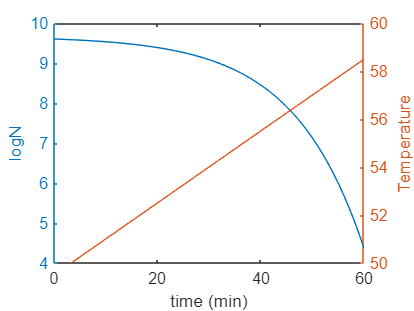


%plot two-axis plot
yyaxis left
plot(t,logN);
ylabel('logN');
%to set yleft axis limits, can use
axis([0 60 round(min(logN)) round(max(logN))])

yyaxis right
plot(t,Temp);
ylabel('Temperature');
%to set yright axis limits, can use
axis([0 60 round(min(Temp)) round(max(Temp),-1)]) %The -1 rounds to the nearest multiple of 10
xlabel('time (min)')


%save values of logN50, Temp50
[C,I]=find(t==50,1)

C =      1

I =     51

logN50=    logN(I)    

logN50 =    7.129088580427309

Temp50=    Temp(I)    

Temp50 =   56.996231741763381